# Hybrid powertrain - modeling

*Ing. David Vošahlík*

## Introduction

The modeling activity covered in this seminar will lead to P2 configuration hybrid powertrain high fidelity model. Some phenomenas still have to be neglected in order to make the model usable for Power Split (PS) control, which will be the ultimate goal of following seminar. **This script will be used within 2 seminars. **In the first the MGU, ICE and Battery should be modelled, which will be graded. The rest in the second one, which will not be graded. The vehicle hybrid powertrain consists of at least two power sources:

- The battery powered e-motor. It is often called Motor Generator Unit (**MGU**)

- Other power source. Mostly it is an Internal Combustion Engine (**ICE**)

Then the rest of the powertrain consits of building blocks mentioned below. 

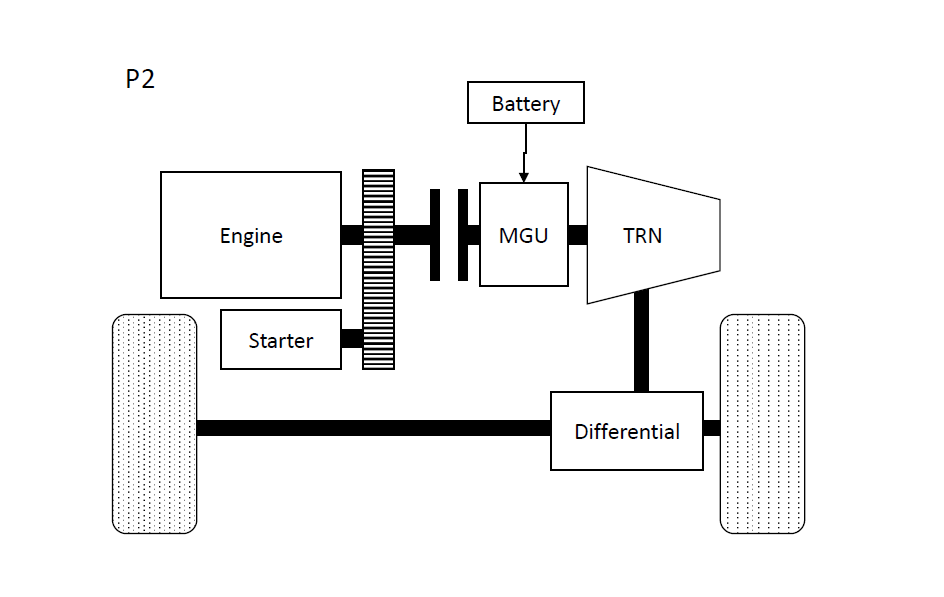

### **Battery **

Battery is device for storage of chemical energy which can be transfered to the electrical power. However, the battery system has dynamics (more detials on other seminar). 

For the modelling ***the 2RC equivalent circuit will be used. ***

You should be already having impelemented this model from previous seminar. Please use this one, just ensure the executability of the model.


$$$\left[\matrix{
\textbf{Inputs}& \text{Current} \cr
\textbf{Outputs}&\text{Terminal voltage}\cr
\textbf{States}&\text{V1, V2, SOC} }
\right]$$$
 

### **MGU **

An electromechanical device that transforms electrical power to mechanical and viceversa. The electrical current is proportional to mechanical torque through motor constant. The motor efficiencies shouldn't be also forgotten. For the purpose of PS the dynamics will be neglected as it is very fast compared to the other dynamic states in the powertrain.

For the modelling ***the MGU is just gain representing the current to torque conversion (and vice versa). The current is calculated from the power MGU consumes and the battery voltage (energy preservation law). Implement also efficiency of the mechanical/electrical energy conversion.***


$$$\left[\matrix{
\textbf{Inputs}& \text{Torque MGU, Speed MGU, Battery Voltage} \cr
\textbf{Outputs}&\text{Current MGU}\cr
\textbf{States}&\text{-} }
\right]$$$


Please implement the prepared template at the bottom of the script (***MGUOutput***). Use constants from *InitializeCar.m* function.

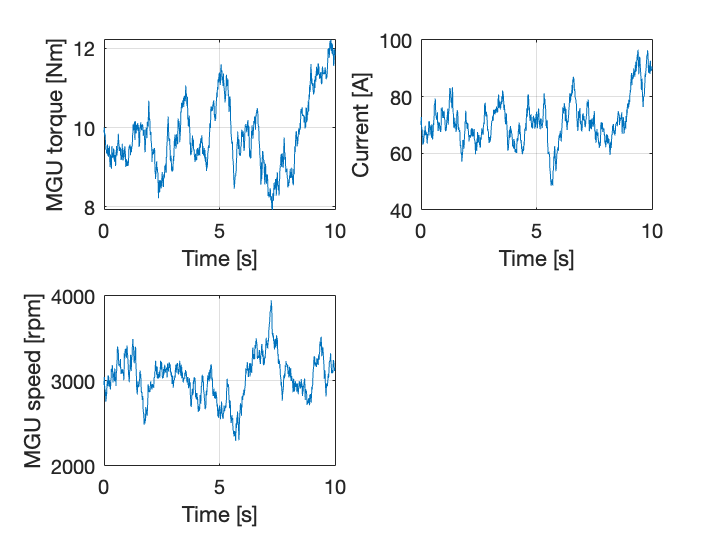

%% Let's try how the MGU behaves
car = InitializeCar();
% Time vector [s]
time = 0:0.01:10;
% MGU torque request [rpm] 
MGU_Tq = 10*ones(1,numel(time)) + movmean(10*randn(1, numel(time)), 100);
% MGU speed [rpm]
MGU_Spd = 3000*ones(1,numel(time)) + movmean(2000*randn(1, numel(time)), 50);
% Battery voltage [V]
Bat_Volt = 45*ones(1,numel(time));

% MGU current [A] vector initialization
MGU_Curr = zeros(1,numel(time));
% order the signals into the vector
u_mgu = [MGU_Tq;MGU_Spd; Bat_Volt];


% Copmute the outputs. No dynamics is needed to be solved
for i = 1:numel(time)
    MGU_Curr(i) = MGUOutput(u_mgu(:,i), car);
end

% Plot the figures
figure();
clf;
subplot(221);
plot(time, MGU_Tq);
grid on;
xlabel('Time [s]');
ylabel('MGU torque [Nm]');

subplot(222);
plot(time, MGU_Curr);
grid on;
xlabel('Time [s]');
ylabel('Current [A]');

subplot(223);
plot(time, MGU_Spd);
grid on;
xlabel('Time [s]');
ylabel('MGU speed [rpm]');

### **ICE **

A mechanical device that transforms fuel chemical power to mechanical power via combustion. Usually used ICEs have not neglectable dynamics of torque that has to be considered when modeling for PS control.

For the modelling ***the ICE is first order system representing the torque request tracking. Another output is fuel consumption rate, which is a map based on ICE speed and torque.***


$$$\left[\matrix{
\textbf{Inputs}& \text{Torque req, Speed} \cr
\textbf{Outputs}&\text{Torque brk, ICE FC}\cr
\textbf{States}&\text{Torque brk} }
\right]$$$


where sft means shaft and ind means indicated torque - that is the torque produced purely with the fuel (any frictions are not considered in this torque).

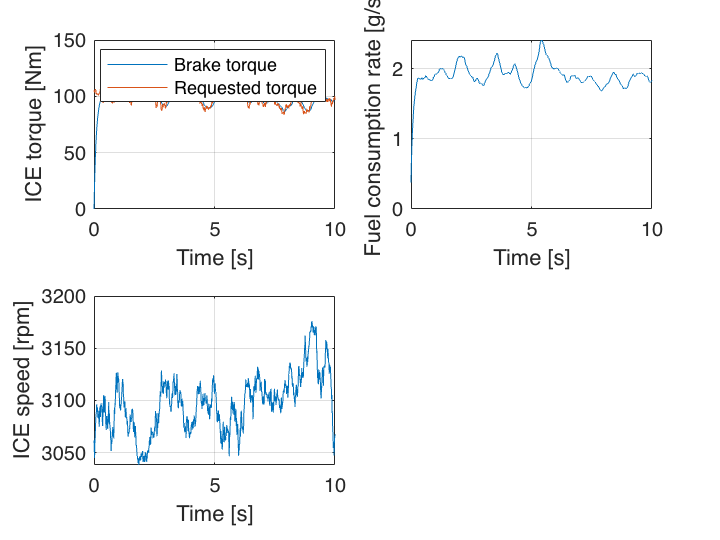

% Let's try how the ICE behaves
% Time vector [s]
time = 0:0.01:10;
% ICE brake torque request [Nm]
ICE_TqReq = 100*ones(1,numel(time)) + movmean(50*randn(1, numel(time)), 50);
% ICE speed [rpm]
ICE_Spd = 3000*ones(1,numel(time)) + movmean(2000*randn(1, numel(time)), 500);


% ICE Fuel consumption [g/s] vector initialization
ICE_FC = zeros(1,numel(time));
% order the signals into the vector
u_ice = [ICE_TqReq;ICE_Spd];
% define the initial state
x0_ICE = 0;
% Simulate the system. Compute the output ICE actual brake torque [Nm]
[~,ICE_Tq] = ode45(@(t,x) myode(t,x,time,u_ice, @(x,t) ICEStateDerivative(x,t,car)), time, x0_ICE);
ICE_Tq = ICE_Tq.';
% Compute the output for the inputs
for i = 1:numel(time)
    y = ICEOutput(ICE_Tq(i), u_ice(:,i), car);
    ICE_FC(i) = y(2);
end

% Plot the important signals
figure();
clf;
subplot(221);
plot(time, ICE_Tq);
hold on;
plot(time, ICE_TqReq);
grid on;
xlabel('Time [s]');
ylabel('ICE torque [Nm]');
legend('Brake torque', 'Requested torque');

subplot(222);
plot(time, ICE_FC);
grid on;
xlabel('Time [s]');
ylabel('Fuel consumption rate [g/s]');

subplot(223);
plot(time, ICE_Spd);
grid on;
xlabel('Time [s]');
ylabel('ICE speed [rpm]');

## **Second seminar**

The following content is part of a following seminar.

### **Gear Shifting Strategy (GSS)**

GSS is a strategy to shift the gears so that the ICE and MGU will be operated at the most efficient conditions. The GSS has usually three inputs -> Current gear, Vehicle (or wheel) velocity, and Driver torque request (Accelerator pedal position). The GSS decides when to switch the gears, based on these. Usually, higher driver torque requests and low speeds tend to downshifts, whereas the low torque requests and/or higher speeds means upshifting. A hysteresis is required in the gear selection otherwise the transimission would start oscilating.

Your task will be to implement a GSS based on vehicle speed thresholds defined in the constants script (*InitializeCar.m*)

The speeds are however just one dimension. The next dimension is APS - Accelerator Pedal Position. The APS is 0 to 100%. Let's assume the APS will linearly** scale the speeds within the plus minus 3 km/h. **Example:

Vehicle velocity = 14 km/h, Current gear = 1, Threshold speed = 15, and APS = 50%. To compute the threshold speed for the current APS:


$$\textrm{SpdThr}=15\left(\textrm{First}\;\textrm{threshold}\;\textrm{for}\;\textrm{upshift}\right)+3\;-\;6*\textrm{APS}\;=18-6*0\ldotp 5=15\;$$


The threshold was computed to be 15km/h therefore the gear change request is not made. If the APS would be 75%, the threshold would be 13.5 and the gear change request should be issued in this case.

Please implement ***GSS*** function placed at the bottom of the script (functions are allowed only at the script end :( - unfortunatelly not right here.) Use constants from *InitializeCar.m* function.

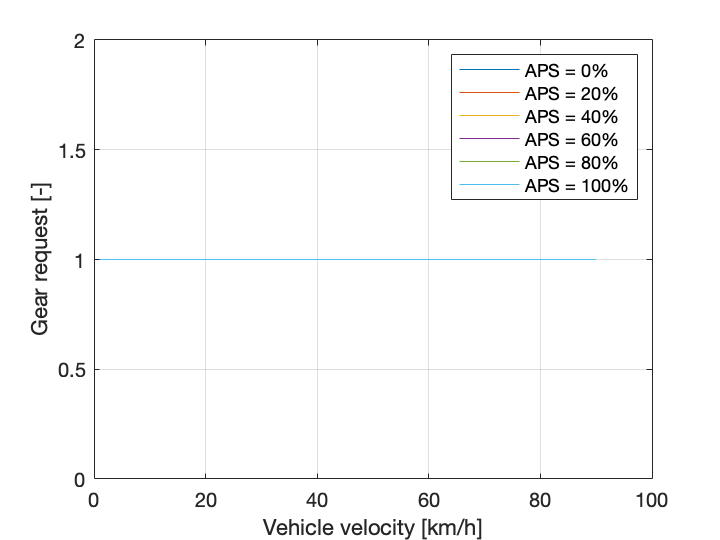

% Let's try how the GSS behaves
% Setup the constants
car = InitializeCar(); 
% create a vehicle velocity [km/h] vector and other derived test signals
Veh_Spd = 1:1:90; 
% Compute the APS (Accelerator pedal position) [%] -> normalized driver torque demand
APS = (0:20:100)*0.01; 
% Initialize the gears vector [-]
Gears = ones(numel(APS), numel(Veh_Spd));
% Initialize the figure and the legened for plotting
leg = cell(numel(APS), 1);
figure();
clf;
% Simulate the shifting strategy in a loop of APS and rising velocities
for i = 1:numel(APS)
    for j = 2:numel(Veh_Spd)
        % Copmute the next requested gear [-]
        Gears(i,j) = GSS(APS(i), Veh_Spd(j), Gears(i,j - 1), car);
    end
    % Plot the gear number for the particular APS as function of increasing vehicle speed
    plot(Veh_Spd, Gears(i,:));
    hold on;
    leg{i} = ['APS = ' num2str(APS(i)*100) '%'];
end
% Some plotting stuff
legend(leg{:});
xlabel('Vehicle velocity [km/h]');
ylabel('Gear request [-]');
grid on;

### **Transimssion** 

A mechanical device that transforms engine side mechanical rotational power to the wheel side rotational power. For hybrid powertrain it is mostly equipped with automatic gear box with automatic gear shifting strategy. The transmission can have different number of gears ranging from 5 to 8 and possibly more. Most commonly used type of transmission is Dual Clutch Transmission (DCT) - more on that can be found, e.g., [here](https://en.wikipedia.org/wiki/Dual-clutch_transmission). Modelling of the transimission is quite straightforward (the level of detail needed for power split control). 

For the modelling we will assume that the shafts on input and output are rigid, the gear change is following the gear request just with delay and the efficiency will be constant (not depending on any wear, tempreture, load, etc.). This reduces the ***model to be just simple gain (depending on the gear selection) and a delay for chaning the gear.***

Your task will be to implement a transmission model into the prepared template at the bottom of the script (***TrsmStateTransition*** and ***TrsmOutput***). Please implement it as a **discrete-time** model.


$$$\left[\matrix{
\textbf{Inputs}& \text{Torque pwr, Speed whl, Gear req} \cr
\textbf{Outputs}&\text{Torque whl, Speed pwr}\cr
\textbf{States}&\text{Gear, Counter} }
\right]$$$


where pwr means powertrain side (ICE and MGU side) and whl means wheels side. The differential will be modeled as part of the transmission. The differential ratio will be included in the gear ratio. Use constants from *InitializeCar.m* function.

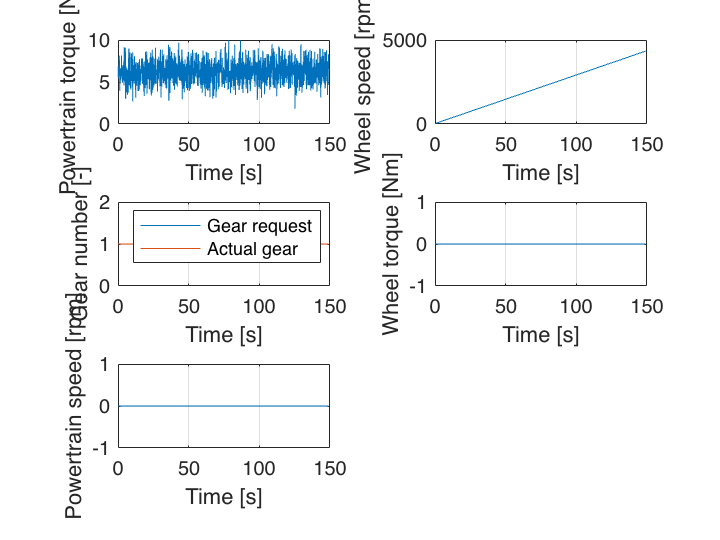

% Let's try how the transmission behaves      

% create a vehicle velocity vector and other derived test signals
Veh_Spd = 1:0.1:150; 
% Driver torque request [Nm] at wheels. Usually this is the signal you get from mapping of acceleration pedal
Drvr_TqReq = 50*ones(1, numel(Veh_Spd)) + 10*randn(1, numel(Veh_Spd));
% Compute the APS (Accelerator pedal position) [%] -> normalized driver torque demand
APS = Drvr_TqReq/130; 
% Wheel torque [Nm] - output of the transmission model
Whl_Tq = zeros(1, numel(Veh_Spd));
% Powertrain speed [rpm] (ICE + MGU side) vector initialization
Pwr_Spd = zeros(1, numel(Veh_Spd));
% Powertrain torque request [Nm] (ICE + MGU side) vector initialization
Pwr_Tq = zeros(1, numel(Veh_Spd));
% Gear request [-] vector initialization
Trsm_GrNxt = zeros(1, numel(Veh_Spd));
% Actual gear [-] vector
Gear = 1*ones(1, numel(Veh_Spd));
% Wheel speed [rpm]
Whl_Spd = Veh_Spd/car.Whl_r/(2*pi)*60;
% Sampling time [s]
Ts = 0.1;
% Time vector [s]
time = cumsum(Ts*ones(1, numel(Veh_Spd)));

% initial state of transmission
xk_trsm = [1;0];

% Simulate the Transmission
for k = 1:numel(Veh_Spd)
    
    % Compute the gear request via GSS
    Trsm_GrNxt(k) = GSS(APS(k), Veh_Spd(k), xk_trsm(1), car);
    % Compute the powertrain torque request
    Pwr_Tq(k) = Drvr_TqReq(k)/car.Trsm.GearRatios(xk_trsm(1));
    % input vector
    u_trsm = [Pwr_Tq(k); Whl_Spd(k); Trsm_GrNxt(k)];
    % save the actual gear for plotting
    Gear(k) = xk_trsm(1);
    
    % Compute the transmission output
    [y_trsm] = TrsmOutput(xk_trsm, u_trsm, car);
    % save the output signals
    Whl_Tq(k) = y_trsm(1);
    Pwr_Spd(k) = y_trsm(2);

    % Perform next time step transition
    xk_trsm = TrsmStateTransition(xk_trsm, u_trsm, Ts, car);
end

% Plot the simulation
figure();
clf;
subplot(321);
plot(time, Pwr_Tq);
xlabel('Time [s]');
ylabel('Powertrain torque [Nm]');
grid on;
subplot(322);
plot(time, Whl_Spd);
xlabel('Time [s]');
ylabel('Wheel speed [rpm]');
grid on;
subplot(323);
plot(time, Trsm_GrNxt);
xlabel('Time [s]');
ylabel('Gear number [-]');
hold on;
plot(time, Gear);
legend('Gear request', 'Actual gear');
grid on;
subplot(324);
plot(time, Whl_Tq);
xlabel('Time [s]');
ylabel('Wheel torque [Nm]');
grid on;
subplot(325);
plot(time, Pwr_Spd);
xlabel('Time [s]');
ylabel('Powertrain speed [rpm]');
grid on;

### **Clutch **

A mechanical device which conects two shafts. The most commonly used clutch is dry friction clutch. There can be even more than one clutch in the vehicle. Typically one clutch is right behid the ICE. That one is disengaged when the ICE is off, so that it does not produce any negative friction torque to the crankshaft. Another one can be between transmission and wheels so that the neutral can be chosen.

For the modelling purposes ***the clutch is first order filter with time constant corresponding to the clutch engagement time.***


$$$\left[\matrix{
\textbf{Inputs}& \text{Torque ice, Speed mgu, Engage req} \cr
\textbf{Outputs}&\text{Torque mgu, Speed ice}\cr
\textbf{States}&\text{Engagement} }
\right]$$$


where mgu means mgu side and ice means ice side. Please implement prepared templates at the bottom of the script (***CltchStateDerivative*** and ***CltchOutput***). Use constants from *InitializeCar.m* function.

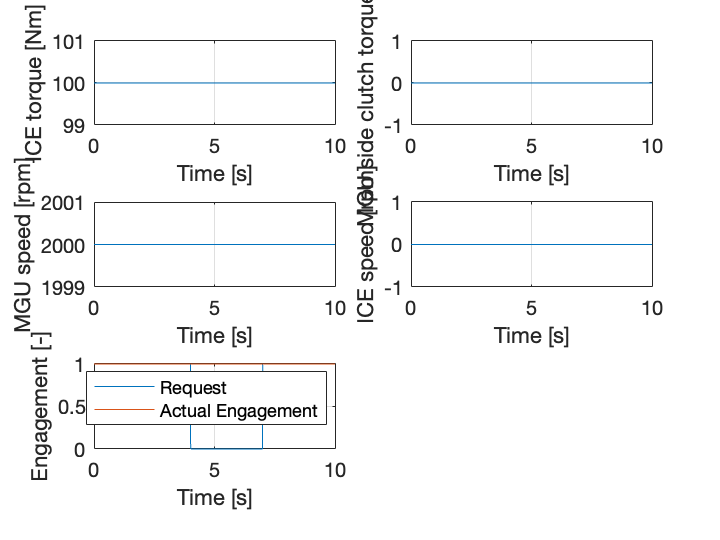

% Let's try how the Clutch behaves
% Time vector [s]
time = 0:0.01:10;
% ICE torque [Nm] (ICE side) vector initialization
ICE_Tq = 100*ones(1,numel(time));
% MGU speed [rpm] (MGU side) vector initialization
MGU_Spd = 2000*ones(1,numel(time));
% Clutch engagement request [-] vector initialization
Clu_EngReq = ones(1,numel(time));
Clu_EngReq(time > 4 & time < 7) = 0;

% MGU torque [Nm] vector initialization
MGU_Tq = zeros(1,numel(time));
% ICE speed [rpm] vector initialization
ICE_Spd = zeros(1,numel(time));
% order the signals into input vector
u_cltch = [ICE_Tq;MGU_Spd;Clu_EngReq];
% Do the simulation
[~,Clu_EngAct] = ode45(@(t,x) myode(t,x,time,u_cltch, @(x,t) CltchStateDerivative(x,t,car)), time, 1);

% Copmute the outputs
for i = 1:numel(Clu_EngAct)
    y = CltchOutput(Clu_EngAct(i), u_cltch(:,i));
    MGU_Tq(i) = y(1);
    ICE_Spd(i) = y(2);
end

% Plot all the important signals
figure();
clf;
subplot(321);
plot(time, ICE_Tq);
grid on;
xlabel('Time [s]');
ylabel('ICE torque [Nm]');

subplot(322);
plot(time, MGU_Tq);
grid on;
xlabel('Time [s]');
ylabel('MGU side clutch torque [Nm]');

subplot(323);
plot(time, MGU_Spd);
grid on;
xlabel('Time [s]');
ylabel('MGU speed [rpm]');

subplot(324);
plot(time, ICE_Spd);
grid on;
xlabel('Time [s]');
ylabel('ICE speed [rpm]');

subplot(325);
plot(time, Clu_EngReq);
hold on;
plot(time, Clu_EngAct);
grid on;
xlabel('Time [s]');
ylabel('Engagement [-]');
legend('Request', 'Actual Engagement');

## Block interconnection

The implemented blocks will be interconected here according to the P2 configuration. For sake of simplicity the starter will be ommited. A simple test scenario is prepared here for you to see if your model behaves reasonably.

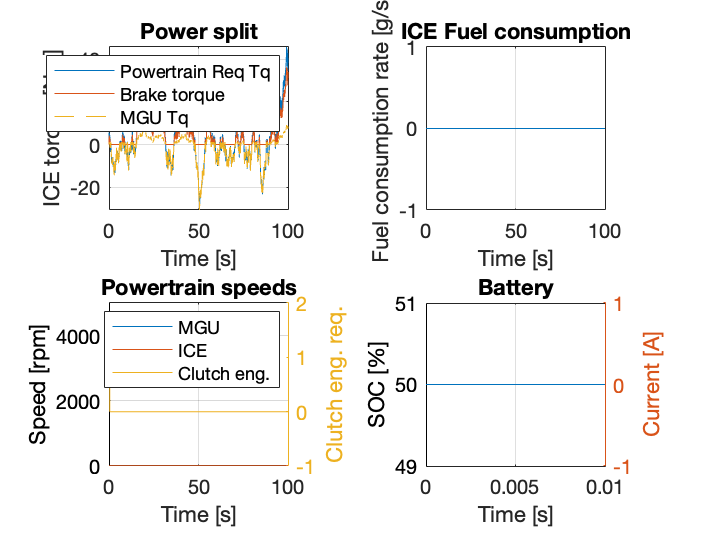

 % Time vector [s]
time = 0:0.01:100;
% create a vehicle velocity vector and other derived test signals
Veh_Spd = max(2, cumsum(0.01*ones(1, numel(time))) + 2 + movmean(10*randn(1, numel(time)), 100));
% Driver torque request [Nm] at wheels. Usually this is the signal you get from mapping of acceleration pedal
Drvr_TqReq = 30*ones(1, numel(time)) + movmean(2000*randn(1, numel(time)), 500);
% Compute the APS (Accelerator pedal position) [%] -> normalized driver torque demand
APS = Drvr_TqReq/130;
Cltch_engReq = 1;
 % states [ICE_Tq, Bat_current, Bat_U1, Bat_U2, Bat_SOC, trsm_gear, trsm_counter, cltch_eng]
x0_P2 = [0; 0; 0; 0; 50; 1; 0; 1];

x = zeros(numel(x0_P2), numel(time));
x(:,1) = x0_P2;
y = zeros(4, numel(time));
u = zeros(5, numel(time));
for k = 1:numel(time)
    if Drvr_TqReq(k) < 10
        ICE_TqReq = 0;
        Cltch_engReq = 0;
    else
        ICE_TqReq = .8*Drvr_TqReq(k)/car.Trsm.GearRatios(x(6,k));
    end

    if Drvr_TqReq(k) > 15 && x(8,k) < 0.01
         Cltch_engReq = 1;
    end
    
    MGU_TqReq = Drvr_TqReq(k)/car.Trsm.GearRatios(x(6,k)) - ICE_TqReq;
    u(:,k) = [ICE_TqReq; MGU_TqReq; Veh_Spd(k); APS(k); Cltch_engReq];
    if k < numel(time)
        [x(:,k + 1), y(:,k)] = P2Powertrain(x(:,k),u(:,k),car, Ts);
    else
        [~, y(:,k)] = P2Powertrain(x(:,k),u(:,k),car, Ts);
    end
end

% Plot the important signals
figure();
clf;
subplot(221);
plot(time, Drvr_TqReq./car.Trsm.GearRatios(x(6,:))')
hold on;
plot(time, x(1,:));
plot(time, u(2,:), '--');
grid on;
xlabel('Time [s]');
ylabel('ICE torque [Nm]');
legend('Powertrain Req Tq', 'Brake torque', 'MGU Tq');
title('Power split');

subplot(222);
plot(time, y(1,:));
grid on;
xlabel('Time [s]');
ylabel('Fuel consumption rate [g/s]');
title('ICE Fuel consumption');

subplot(223);
plot(time, y(3,:)); % Pwr_Spd
hold on;
plot(time, y(4,:)); % ICE_Spd
grid on;
xlabel('Time [s]');
ylabel('Speed [rpm]');
ylim([-10 5000]);
yyaxis right;
plot(time, u(5,:)); % Cltch_engReq
grid on;
xlabel('Time [s]');
ylabel('Clutch eng. req.');
ylim([-1 2]);
legend('MGU', 'ICE', 'Clutch eng.');
title('Powertrain speeds');


subplot(224);
plot(time, x(5,:));
grid on;
xlabel('Time [s]');
ylabel('SOC [%]');
title('Battery');
yyaxis right;
plot(time, x(2,:)); % Cltch_engReq
grid on;
xlabel('Time [s]');
ylabel('Current [A]');

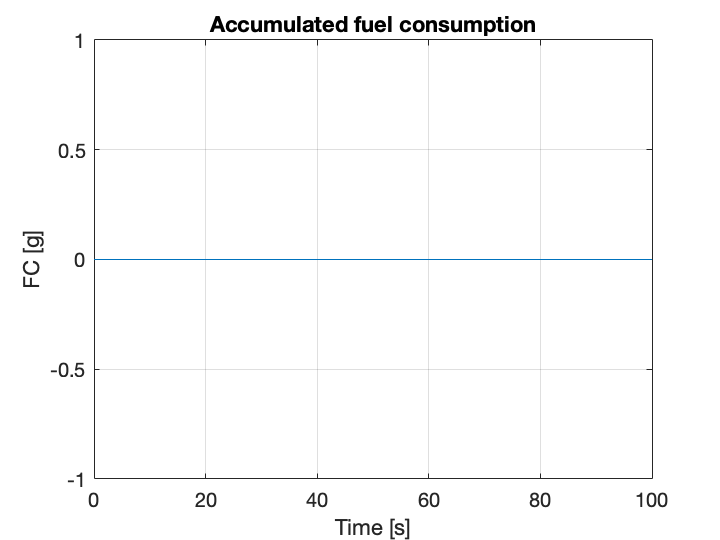


figure();
clf;
plot(time, cumsum(y(1,:)*Ts))
grid on;
xlabel('Time [s]');
ylabel('FC [g]');
title('Accumulated fuel consumption');

function [y_MGU] = MGUOutput(u_MGU, car) % output function for MGU - no dynamics
% u_MGU - is the input [Torque MGU [Nm], Speed MGU [rpm], Battery Voltage [V]]
% y_MGU - is the output [Current MGU [A]]
% car - structure with the parameters. Check InitializeCar.m function

% IMPLEMENT output function for MGU model. Use the constants defined in the car.MGU
Tq  = u_MGU(1);
N   = u_MGU(2);
w   = 2*pi*N/60;
V   = u_MGU(3);
eta = interp2(car.MGU.eta.Spd, car.MGU.eta.Tq,car.MGU.eta.eta,N,Tq);
if (Tq>0)
    y_MGU = (1/eta)*Tq*w/V;
else
    y_MGU = eta*Tq*w/V;
end

end

function [xDot_bat] = BatStateDerivative(x_bat, u_bat, car)
% State derivative function for battery - continuous time dynamics
% x_bat - is the state [U1 [V], U2 [V], SOC [%]]
% u_bat - is the input [Current [A]]
% car - structure with the parameters. Check InitializeCar.m function

    C1 = car.Bat.C1;
    C2 = car.Bat.C2;
    eta = car.Bat.eta;
    C = car.Bat.C;
    R1 = car.Bat.R1;
    R2 = car.Bat.R2;

    B = [1/C1;1/C2;-eta/C];
    A = [-1/(R1*C1) 0 0; 0 -1/(R2*C2) 0; 0 0 0];
    xDot_bat = A*x_bat + B*u_bat;
% Implement the continuous time dynamic equations
end

function [y_bat] = BatOutput(x_bat, u_bat, car)
% output function for battery - continuous time dynamics
% x_bat - is the battery state [U1 [V], U2 [V], SOC [%]]
% u_bat - is the battery input [Current [A]]
% y_bat - is the battery output [Terminal voltage [V]]
% car - structure with the parameters. Check InitializeCar.m function
    R0 = car.Bat.R0;
    D = -R0;
    C = [-1 -1 0];
    y_bat = ocv(x_bat(3)) + C*x_bat + D*u_bat;
% Compute the terminal voltage output
end


function voltage = ocv(SOC)
% Copmute the open circuit voltage [V] for the provided SOC [%]
voltage = 38 + 0.295*SOC - 0.01*SOC^2 + 1.9694e-04*SOC^3 - 1.652e-06*SOC^4 + 5.234e-09*SOC^5;
end


function [xDot_ice] = ICEStateDerivative(x_ice, u_ice, car) % State derivative function for ICE - continuous time dynamics
% x_ice - is the state [brake torque [Nm]]
% u_ice - is the input [brake torque req [Nm], speed [rpm]]
% car - structure with the parameters. Check InitializeCar.m function

% IMPLEMENT a state derivative function for ICE model. Use the constants defined in the car.ICE
    tau = car.ICE.tau;
    xDot_ice = (1/tau)*(u_ice(1)-x_ice);
end

function [y_ice] = ICEOutput(x_ice, u_ice, car) % output function for ICE - continuous time dynamics
% x_ice - is the state [brake torque [Nm]]
% u_ice - is the input [brake torque req [Nm], speed [rpm]]
% y_ice - is the output [actual brake torque [Nm], ICE FC [g/s]]
% car - structure with the parameters. Check InitializeCar.m function
% IMPLEMENT an output function for ICE model. Use the constants defined in the car.ICE
    Tq = x_ice;
    N = u_ice(2);
    FC = interp2(car.ICE.FC.Spd, car.ICE.FC.Tq,car.ICE.FC.FC,N,Tq);
    y_ice = [Tq; FC];
end


function [Trsm_GrNxt] = GSS(APS, Veh_V, Trsm_GrAct, car) % Gear shifting strategy
% APS - Accelerator pedal position [%]
% Veh_V - Vehicle velocity [km/h]
% Trsm_GrAct - Actual gear [-]
% car - structure with the parameters. Check InitializeCar.m function

% IMPLEMENT a gear shifting strategy. Use the constants defined in the car.GSS
    Trsm_GrNxt = Trsm_GrAct;
end

function [xk1_trsm] = TrsmStateTransition(xk_trsm, u_trsm, Ts, car) % State transition function for transmission - discrete time dynamics
% xk1_trsm - is the next time step Ts + 1 value of the transmission state [transmission gear number [-], counter [-]]
% u_trsm - is the transmission input [Torque pwr [Nm], Speed whl [rpm], Gear req[-]]
% Ts - The sampling time for the transmission.
% car - structure with the parameters. Check InitializeCar.m function


% IMPLEMENT a state transition function for transmission. Use the constants defined in the car.Trsm


    xk1_trsm = xk_trsm;
end

function [y_trsm] = TrsmOutput(xk_Trsm, u_trsm, car) % output function for transmission
% xk_trsm - is the next time step Ts + 1 value of the transmission state [transmission gear number [-], counter [-]]
% u_trsm - is the transmission input [Torque pwr [Nm], Speed whl [rpm], Gear req[-]]
% y_trsm - is the transmission output [Torque whl [Nm]; Speed pwr [rpm]]
% car - structure with the parameters. Check InitializeCar.m function

% IMPLEMENT an output function for transmission. Use the constants defined in the car.Trsm

    y_trsm = zeros(2,1);
end

function [xDot_cltch] = CltchStateDerivative(x_cltch, u_cltch, car) % State derivative function for clutch - continuous time dynamics
% x_cltch - is the clutch state [Engagement [-]]
% u_cltch - is the clutch input [Torque_eng [Nm], Speed_mgu [rpm], Engagement_req [-]]
% car - structure with the parameters. Check InitializeCar.m function


% IMPLEMENT a state derivative function for clutch model. Use the constants defined in the car.Cltch
xDot_cltch = 0;
end

function [y_cltch] = CltchOutput(x_cltch, u_cltch) % output function for clutch
% x_cltch - is the clutch state [Engagement [-]]
% u_cltch - is the clutch input [Torque_eng [Nm], Speed_mgu [rpm], Engagement_req [-]]
% y_cltch - is the clutch output [Torque mgu [Nm], Speed eng [rpm]]

% IMPLEMENT output function for clutch model. Use the constants defined in the car.Cltch

y_cltch = zeros(2,1);
end





function dxdt = myode(t,x,ut,u, fun) % helper function to use within ode45 solver function
uInterp = zeros(size(u, 1), 1);
for i = 1:size(u, 1)
    uInterp(i) = interp1(ut,u(i,:),t); % Interpolate the data set (ut,u) at time t
end
dxdt = fun(x, uInterp); % Evaluate ODE at time t
end

function [x_k1, y] = P2Powertrain(x,u,car, Ts)
 % states [ICE_Tq, Bat_current, Bat_U1, Bat_U2, Bat_SOC, trsm_gear, trsm_counter, cltch_eng]
 % inputs [ICE tqReq, MGU tqReq, Veh_Spd, APS, cltch_engReq]
 % outputs [ICE_FC, Whl_Tq, Pwr_Spd, ICE_Spd]

 x_bat = x(3:5);
 u_bat = x(2);
 [~,x_k1Bat] =  ode45(@(t,x) BatStateDerivative(x, u_bat, car), [0 Ts], x_bat);
 Bat_VTrm = BatOutput(x_bat, u_bat, car);

 Veh_Spd = u(3);
 Whl_Spd = Veh_Spd/car.Whl_r/(2*pi)*60;
 ActGear = x(6);
 Pwr_Spd = TrsmOutput(ActGear, [0; Whl_Spd], car);
 Pwr_Spd = Pwr_Spd(2);

 MGU_Tq = u(2);
 u_MGU = [MGU_Tq; Pwr_Spd; Bat_VTrm];
 Bat_A = MGUOutput(u_MGU, car);

 ICE_Tq = x(1);
 % [Engagement [-]]
 x_cltch = x(8);
 % [Torque_eng [Nm], Speed_mgu [rpm], Engagement_req [-]]
 u_cltch = [ICE_Tq; Pwr_Spd; u(5)];
 % [Engagement [-]]
 [~,x_k1Cltch] =  ode45(@(t,x) CltchStateDerivative(x, u_cltch, car), [0 Ts], x_cltch);


 % [Torque mgu [Nm], Speed eng [rpm]]
 [y_cltch] = CltchOutput(x_cltch, u_cltch);
 Cltch_Tq = y_cltch(1);
 ICE_Spd = y_cltch(2);


 ICE_TqReq = u(1);
 % [brake torque [Nm]]
 x_ice = [ICE_Tq];
 u_ice = [ICE_TqReq; ICE_Spd];
 % [brake torque [Nm]]
 [~,x_k1Ice] =  ode45(@(t,x) ICEStateDerivative(x, u_ice, car), [0 Ts], x_ice);
 [y_ice] = ICEOutput(x_ice, u_ice, car);
 ICE_FC = y_ice(2);



 APS = u(4);
 Trsm_GrNxt = GSS(APS, Veh_Spd, ActGear, car);

 Pwr_Tq = Cltch_Tq + MGU_Tq;
 xk_trsm = [ActGear; x(7)];  % [transmission gear number [-], counter [-]]
 u_trsm = [Pwr_Tq; Whl_Spd; Trsm_GrNxt]; %  [Torque pwr [Nm], Speed whl [rpm], Gear req[-]]
 [y_trsm] = TrsmOutput(xk_trsm, u_trsm, car); % [Torque whl [Nm]; Speed pwr [rpm]]
 xk1_trsm = TrsmStateTransition(xk_trsm, u_trsm, Ts, car);

 Pwr_Spd = y_trsm(2);
 Whl_Tq = y_trsm(1);

 % states [ICE_Tq, Bat_current, Bat_U1, Bat_U2, Bat_SOC, trsm_counter, trsm_gear, cltch_eng]
 x_k1 = [x_k1Ice(end,:)'; Bat_A; x_k1Bat(end,:)'; xk1_trsm; x_k1Cltch(end,:)'];
 % outputs [ICE_FC, Whl_Tq, Pwr_Spd, ICE_Spd]
 y = [ICE_FC, Whl_Tq, Pwr_Spd, ICE_Spd];
 end
